## Patch Antenna on Dielectric Substrat

### Creating Patch Antenna on Low-Epsilon Thin Substrate

Create a rectangular patch antenna with a length of 50 mm and a width of 40 mm on a 90 mm x 70 mm ground plane. The lossless substrate has a dielectric constant of 2.33 and thickness of 1.57mm. The feed is offset by 5.8 mm from the origin along the x-axis.

p1 = patchMicrostrip
p1.Length = 1.54e;
p1.Width = 40e-3;
p1.Height = 1.57e-3;
p1.GroundPlaneLength = 90e-3;
p1.GroundPlaneWidth = 70e-3;
p1.FeedOffset = [5.8e-3 0];

Selecting FR4 substrate

openDielectricCatalog
p1.Substrate = dielectric(Name="FR4",EpsilonR=2.33);

Convert the patch model to the stack representation and model the feed.

pb1 = pcbStack(p1);
pb1.FeedDiameter = sqrt(2)*1e-3;
pb1.FeedViaModel = "square"

#### Visualising the antenna element

figure
show(pb1)

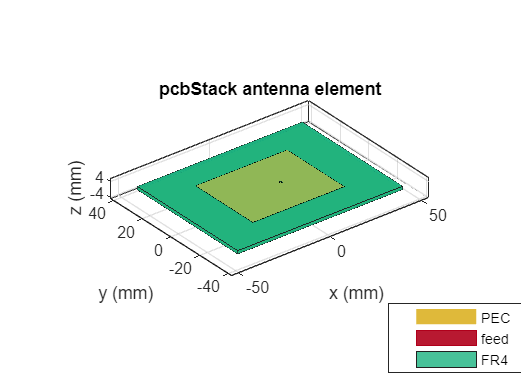

Below is the mesh used to model the antenna. The triangles are used to discretize the metal regions of the patch, and tetrahedra are used to discretize the volume of the dielectric substrate in the patch. These are indicated by the colors yellow and green respectively

figure
mesh(pb1,MaxEdgeLength=0.01,MinEdgeLength=0.003)

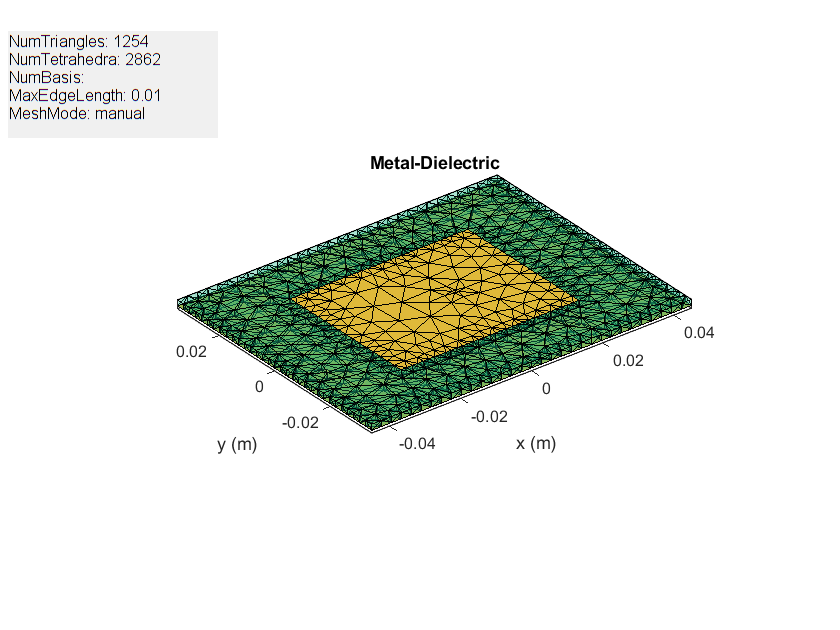

The impedance of the antenna shows a resonance at 2.37 GHz.

figure
impedance(pb1,linspace(3.2e9,3.9e9,21))

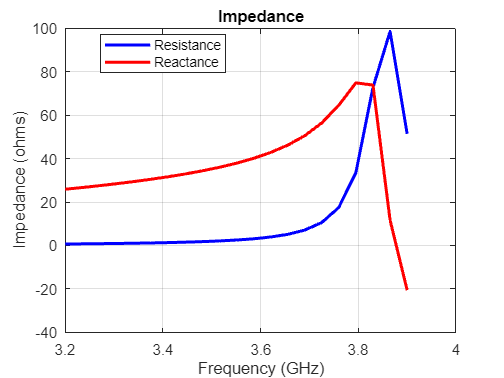

The antenna pattern at resonance also shows uniform illumination above the ground plane with minimum leakage below it.

figure
pattern(pb1, 3.865e9)